# **Matlab案例代码解析**

## 3. 科学计算案例

### 3.1 数值分析

#### 3.1.3  显式Euler、隐式Euler、改进Euler、Runge-Kutta

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)


$$\left\{
\begin{array}{l}
y'=x+y, & 0\leq x \leq 5\\
y(0)=0
\end{array} 
\right.$$


## 显式 Euler


$$y_n = y_{n-1} + h*f(x_{n-1},y_{n - 1})$$


## 隐式 Euler


$$y_{n+1} = y_n + h*f(x_{n+1},y_{n +1})$$


### 迭代计算


$$\left\{
\begin{array}{l}
y_{n+1}^0 = y_n + h*f(x_n, y_n) \\
y_{n+1}^{k+1}=y_n+h*f(x_{n+1},y_{n+1}^k)
\end{array} 
\right.$$


## 改进 Euler


$$\left\{
\begin{array}{l}
y_p=y_n+h*f(x_n,y_n) \\
y_q = y_n + h*f(x_{n+1},y_p) \\
y_{n+1} = 0.5 * (y_p + y_q)
\end{array} 
\right.$$


## Runge-Kutta


$$\left\{
\begin{array}{l}
y_{n+1} = y_n + \frac{h}{6}(k_1 + 2k_2 + 2k_3 + k_4)\\
k_1 = f(x_n,y_n) \\
k_2 = f(t_n + \frac{h}{2}, y_n + \frac{h}{2}k_1) \\
k_3 = f(t_n + \frac{h}{2}, y_n + \frac{h}{2}k_2) \\
k_4 = f(t_n + h, y_n + hk_3)
\end{array} 
\right.$$


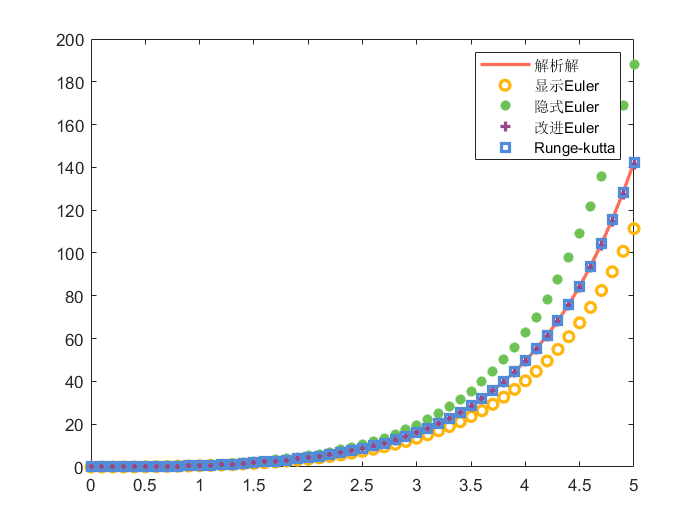

clear;clc;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
func = @(x,y) x + y;
% 显式 Euler
h = 0.1;
x = 0 : h : 5;
N = length(x);
y1 = zeros(1, N);
y1(1) = 0;
for i = 2:N
    y1(i) = y1(i-1) + h * func(x(i-1), y1(i-1));
end

% 隐式 Euler
y2 = zeros(1, N);
y2(1) = 0;
for i = 2:N
    % 显式 Euler 作为初始值迭代计算
    y2i_0 =  y2(i-1) + h * func(x(i-1), y2(i-1));
    y2i_1 = y2(i - 1) + h * func(x(i), y2i_0);
    while abs(y2i_1 - y2i_0) > 1e-6
        y2i_0 = y2i_1;
        y2i_1 = y2(i - 1) + h * func(x(i), y2i_0);
    end
    y2(i) = y2i_1;
end

% 改进 Euler
y3 = zeros(1, N);
y3(1) = 0;
for i = 2:N
    yp = y3(i-1) + h * func(x(i-1), y3(i-1));
    yq = y3(i-1) + h * func(x(i), yp);
    y3(i) = 0.5 * (yp + yq);
end

% Runge-kutta
y4 = zeros(1, N);
y4(1) = 0;
for i = 2:N
    k1 = func(x(i-1), y4(i-1));
    k2 = func(x(i-1) + h/2, y4(i-1) + h/2*k1);
    k3 = func(x(i-1) + h/2, y4(i-1) + h/2*k2);
    k4 = func(x(i-1) + h, y4(i-1) + h*k3);
    y4(i) = y4(i-1) + h/6*(k1 + 2*k2 + 2*k3 + k4);
end

% 画图对比
% 解析解
% syms y(x)
% y_sol(x) = dsolve(diff(y,x) == x+y, y(0) == 0)
y = exp(x) - x - 1;
plot(x, y, x, y1, 'o', x, y2, '*', x, y3, '+', x, y4, 's', 'LineWidth', 2);
legend('解析解', '显示Euler', '隐式Euler', '改进Euler', 'Runge-kutta');
set(gca, 'colororder', all_themes{1});